#  Advanced Scientific Concepts Llc, proprietary information

Extract data from the SEQ file and process

% Modified by Crandall, 1/11/2023
% Modified by Lompado, 01/20/23

## Initialization

Environment setup

WorkingDir = 'C:\Users\art.lompado\Documents\MATLAB\3D Pt Cloud Processing\Initial work - TigerCub Imagery\Kubota ATV';

TigerCub vitals

% FPA constants 
FPAsz = [128 128];
xpxl = 1:FPAsz(1);
ypxl = 1:FPAsz(2);
numpix = FPAsz(1) * FPAsz(2);  % 16384 for 128^2
bitdepth = 12;

% Where did this come from?  Does TigerCub run at 20 hz?
frame_interval = 1/20;

% Lens constants 
fov = 30*[1 1];  % [az el]
az = linspace(-fov(1)/2, fov(1)/2, FPAsz(2));
el = linspace(-fov(2)/2, fov(2)/2, FPAsz(1));

Initialize FoV "matrices" (2D matrices - (128 x 128)) and "arrays" (1D vectors - (1 x 16384))

** Apparently that's how vectors are identified in Matlab (as arrays).  See "Array vs. Matrix Operations" in the documentation.  **

az_matrix = repmat(az, [numel(el) 1]);       
el_matrix = repmat(flip(el)', [1 numel(az)]);

az_array = az_matrix(:);
el_array = el_matrix(:);

Target file structure vitals

fileheader = 1024;
fstartri = 512;    % Frame header size?.
framesize = 66960; % Where does this come from? (Hint: it's NOT (128^2*4)+512 = 66048)

## Load data

[fname, PathName] = uigetfile('*.seq', 'Select the file to read');  % filename:'03-14-2023_01_00_11PM Kubota w 4ftx4ft 62%.SEQ'
fnamewPath = strcat(PathName,fname);

% Open file 
fid1 = fopen(fname);
eof = fseek(fid1, 0, 'eof'); 
file_size = ftell(fid1);

% Select frames to process. For all frames, set startFrame = 1 and endFrame = allFrames
allFrames = (file_size - fstartri - fileheader)/framesize;
startFrame = 1;
endFrame = allFrames; 
iframe = startFrame:endFrame;
nframes = endFrame - startFrame + 1;

Load 2D image and range data: 'intensity' is in counts (0->4095), 'range' is in feet (meters?)

% initiate the data matrices with correct sizes for speed
intensity = zeros(FPAsz(1), FPAsz(2), 1);
range = zeros(FPAsz(1), FPAsz(2), 1);

for frame = startFrame:endFrame
    fseek(fid1, fstartri + (frame - 1) * framesize, 'bof');  % start of R&I data
    RIvector = uint32(fread(fid1, numpix, 'uint32', 'l'));
    RIvector = fliplr(flip(reshape(RIvector, FPAsz(1), FPAsz(2))));
    % What's the units on the measured intensity?  Just counts?
    intensity(:,:, frame - iframe(1) + 1) = bitand(RIvector(ypxl, xpxl), (2^bitdepth)-1); 
    range(:,:,frame - iframe(1) + 1) = double(bitshift(RIvector(ypxl, xpxl), -bitdepth))./64;  % 64? 
end

fclose(fid1);

disp(['Frames loaded: ' num2str(frame)])

Frames loaded: 1357


## Normalize raw intensity data 

 Later we'll do some preprocessing on it.

% Normalize each intensity frame
for i = 1:nframes
    normedInt(:,:,i) = intensity(:,:,i)./max(intensity(:,:,i), [], 'all'); % Frame by frame normalization 
end

## Visualize normalized raw intensity data

Do we need named figures in Live Editor mode since we don't have a separate Figure window?

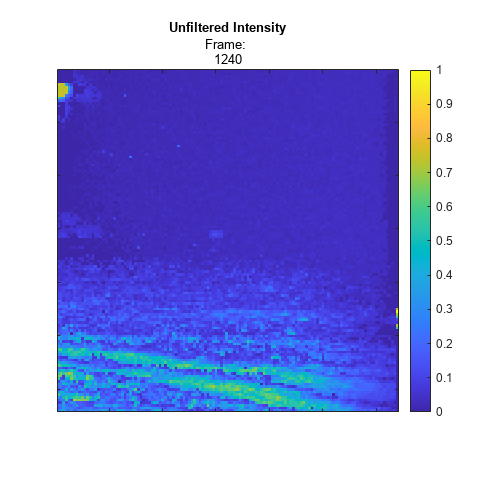

figure();                                     
                                              
for i = 190:50:1250 % 1:nframes 
    set(gcf, "Position",[0 0 500 500]);

    imagesc(normedInt(:,:,i))
    xticklabels({});yticklabels({});
    title("Unfiltered Intensity", ["Frame: ", num2str(i)], 'FontSize', 10);

    colormap("parula"); colorbar; clim([0, 1])
    daspect([1 1 1]);
    drawnow
end 

## Visualize raw range data

 Later we'll do some preprocessing on it.

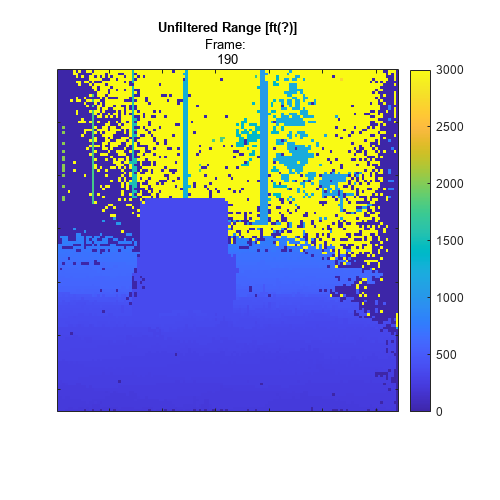

figure(); 

for i = 190:50:1250 % 1:nframes  
    set(gcf, "Position",[0 0 500 500]);

    imagesc(range(:,:,i))
    xticklabels({});yticklabels({});
    title("Unfiltered Range [ft(?)]", ["Frame: ", num2str(i)], 'FontSize', 10);
 
    colormap("parula"); colorbar; clim([0, 3000]) %parula  colorcube
    daspect([1 1 1]);
    drawnow
end

## Filter the data, build pt. clouds into a frame structure

Note:  The filter parameter (outlier = 1) was too stringent. For now I don't use the mask or more correctly, set it to not perform any filtering (outlier = 100) b/c I want the # of pts in each cloud to be the same for every frame b/c that's what they have in the YOLO script.

NOTE: With no filter, data goes out to x > 14,000 which is obviously wrong (correct?) but it keeps everything the same size (i.e., 16384 pts) which the YOLO script wants (I think).  Picture of PC 1160 plotted out to 15000 ft shows a bunch of pts beyond 3400 ft:

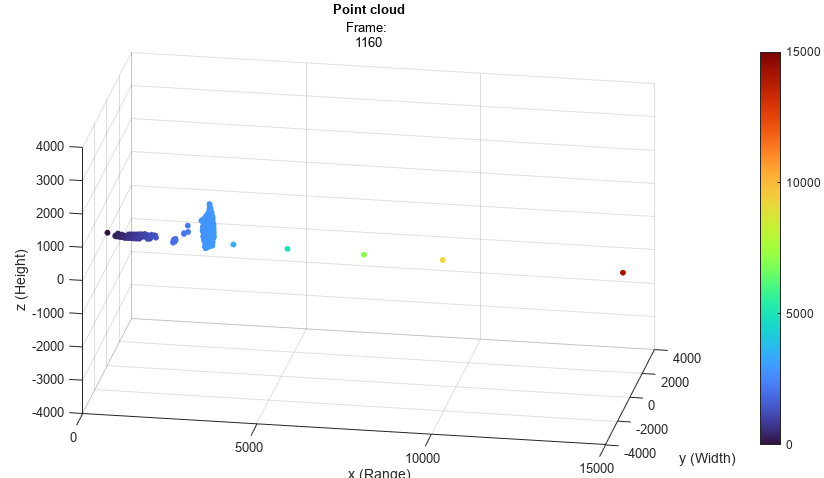boxLabelDatastore

clc % Why clc at the begining of every section? Is that good Matlab programming practice or something?

% Initialize frame structure 
frame = [];

for i = 1:nframes  % loop through frames
    range_matrix = range(:,:,i);
    intensity_matrix = intensity(:,:,i);
    
    range_array = range_matrix(:);
    intensity_array = intensity_matrix(:);

    % remove crazy outliers from the range array. 
    mask = true(size(range_array));
    
    % Filter data w/ a parameter called "outlier" such that outlier -> smaller filters the data more
    outlier = 100; % was 1  

    % Filter the data if it's more than (1 + outlier) * mean 
    mask(range_array > (1 + outlier) * mean(range_array)) = false;
    % Filter the data if it's less than (1 - outlier) * mean 
    mask(range_array < (1 - outlier) * mean(range_array)) = false;

    % Put things in CC 
    [x,y,z] = sph2cart(az_array(mask) * pi/180,...
                       el_array(mask) * pi/180,...
                       range_array(mask));
    xyzPoints = horzcat(x,y,z);

% Unorganized PC: dims = {FPAsz(1)*FPAsz(2), 3}  This was here and parts of the rest 
% of the script depends on it.
    ptCloud = pointCloud(xyzPoints);

    % Stuff out the frame structures w/ processed data
    frame(i).x = x;
    frame(i).y = y;
    frame(i).z = z; 
    frame(i).intensity = intensity_array(mask); 
    frame(i).range = range_array(mask);
    frame(i).ptCloud = ptCloud;

% Organized PC: dims = {FPAsz(1), FPAsz(2), 3} & included intensity
    Org_xyzPoints = reshape(xyzPoints,[FPAsz(1), FPAsz(2), 3]);
    OrgPtClouds(i) = pointCloud(Org_xyzPoints);
    OrgPtClouds(i).Intensity = normedInt(:,:,i); % Use normedInt 
end

Test that we got all the pts in each of the OrgPtClouds. I think(?) this is a YOLO script requirement.  Crude test but suffices for now

% for i = 1:nframes
%     numPts = size(OrgPtClouds(i).Location);
%     test = numPts == [128, 128, 3];
%     times(times(test(1), test(2)), test(3))
% end

## Visualization - 3D pt. clouds w/ scatter3()

Visualize pt. clouds using ListPointPlot3D (Matlab calls it scatter3()).  Much faster than the built-in pcshow()

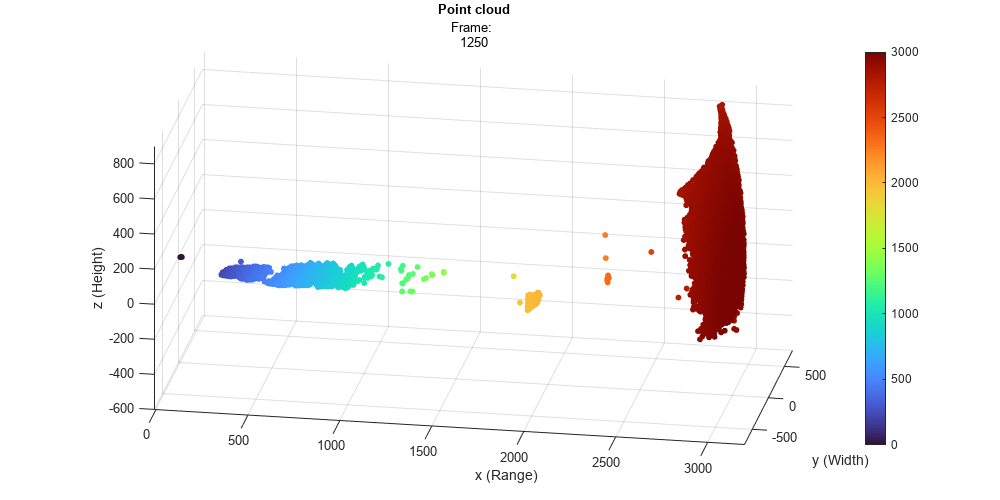

figure();                        
                                 
for i = 190:10:1250 %1:nframes                
    % Pt size in figure
    S = repmat(20, length(frame(i).x), 1); 
   
    ax = gca; % current axes
    set(gcf, "Position",[0 0 1000 500]);

    scatter3(ax, frame(i).x, frame(i).y, frame(i).z, S, frame(i).x, 'filled')
    xlim([-10, 3200]); ylim([-750, 750]); zlim([-600, 900]); view(10, 20)
    xlabel('x (Range)'); ylabel('y (Width)'); zlabel('z (Height)')
    title("Point cloud", ["Frame: ", num2str(i)], 'FontSize', 10);
 
    colorbar; clim([0, 3000]); colormap("turbo"); %turbo colorcube

    daspect([1 1 1]);
    drawnow
end

Note: x is range or depth, z is height, y is width and {0,0,0} is at the sensor.

## Visualization - 3D pt. clouds w/ pcshow() (sloooooow!)

NOTE: Used to need a color function ("rainbowColorMap.m") that was like Jet but it had the x and z channels swapped because x corresponds to range (not z!).  Now, take care of that using pcshow(..., 'Colorsource', "x") so don't need rainbowColorMap.m anymore.

#### ****  Doesn't work!  Only plots the final image.  How do I make the animation live?  ***

#### **** frame(i).ptCloud OR frame(i).ptCloud.Location OR OrgPtClouds(i).Location all don't work. ***

**** Starting to think that pcshow() can not be made live???  ****

figure();     

% loop through frames pt. cloud
for i = 1:50:100 %1:nframes
    set(gcf, "Position",[0 0 1000 500],'Color','black'); 
% OrgPtClouds(i).Location  frame(i).ptCloud.Location
    k = pcshow(frame(i).ptCloud, 'MarkerSize', 20, 'Colorsource', "x", AxesVisibility = "on");
    xlim([-10, 3200]); ylim([-750, 750]); zlim([-600, 900]); view(10, 20) 
    xlabel('x (Range)'); ylabel('y (Width)'); zlabel('z (Height)')
    title("Point cloud", ["Frame: ", num2str(i)], 'FontSize', 10,'Color','white');

    colorbar('Color','white'); clim([0, 2500]); colormap(k, "turbo" ); % turbo  jet  parula

    daspect([1 1 1]);
    drawnow
end

## Range statistics

disp('Frame range statistics')
for i = 1:nframes  %1:50:nframes
    disp([num2str(i) ': mean = ' num2str(mean(frame(i).x),'%.2f') ': stdev = ' num2str(std(frame(i).x),'%.2f')])
end


# I don't use most of this code anymore - just the file save stuff

## Filter the intensity images (again)

This is the preprocessing mentioned above. Tune up intensity images by replacing zeros with the mean of the image (after omitting the zeros) and dividing the image by 16 to put it on a {0, 255} scale - good for windows (don't know if Matlab requires that).

Q: Why do they do this?  Do we want to do this or just leave the zeros?  This will affect the YOLO script so think hard about this. 

Ans: Just use normedInt(...) calculated above

int = intensity;
int(int==0) = NaN; % Replace 0s w/ NaNs

imean = mean(int(:),'omitnan'); 

int(isnan(int(:))) = imean;

int2 = int./16; %This is used below

### Preprocess Range images by filtering 

Tune up the range arrays - do the same thing, replace zeros w/ NaNs, take std dev and mean (w/o NaNs), rng values outside of (mean +/- 5 std dev) gets replaced by the mean (omitting NaNs).  Final rng2 is normalized and then multiplied by OG range max to retain the range.

Q: Again, do we really want this?  This will affect the YOLO script

rng = range;
rng(rng==0) = NaN;

% Q: Why is this here and more importantly, it's on top of the filtering 
%    performed already w/ "mask" in the 6th section.  That was for 
%    outliers but this takes +/- 5 SDs (which will presumably catch 
%    outliers anyway) 

% Also, why do they do it on the whole range array as opposed to
% normalizing each frame individually? Same w/ int above. Seems like
% these things belong in a loop to do calcs on individual frames!

% Filter rng and take only the central +/- 5 SDs
rng(rng>(5*std(rng(:), 'omitnan') + mean(rng(:), 'omitnan'))) = NaN;
rng(rng<(mean(rng(:), 'omitnan') - 5 * std(rng(:), "omitnan"))) = NaN;
rmean = mean(rng(:), 'omitnan');

rng(isnan(rng(:))) = rmean;
%rng2 = rng/max(rng(:))*2^8; % Why multiply the normalized range data by 256?
                             % Perhaps in preparation for saving to file?
                             % Although that requires {0,255} not {1,256}
rng2 = rng;

### Preprocess the Intensity images by contrast stretching 

From the Function pg. for imadjust() : "imadjust(I, stretchlim(I),[]) adjusts the contrast in the image using `stretchlim` to set the limits, and display the result. The example uses the default limits `[0.01 0.99]`, saturating the upper 1% and the lower 1%."

%initiate the J arrays for speed
Ji = zeros(FPAsz(1), FPAsz(2), nframes);
Ji2 = zeros(FPAsz(1), FPAsz(2), nframes);
Jr = zeros(FPAsz(1), FPAsz(2), nframes);
Jr2 = zeros(FPAsz(1), FPAsz(2), nframes);

for i = 1:nframes

    % Intensity images: 16 bits & 8 bits 
%     I = uint16(int(:,:,i));                             %Q: Why have the 16 bit images?  We don't use them.
%     Ji(:,:,i) = imadjust(I, stretchlim(I),[]);
    
%   I = uint8(int2(:,:,i));
    I = int2(:,:,i)/max(int2(:,:,i),[],'all');   % This is normalized intensity
    Ji2(:,:,i) = imadjust(I, stretchlim(I),[]); 

    % Range images: 16 bits & 8 bits 
%     I = uint16(rng(:,:,i));                             %Q: Why have the 16 bit images?  We don't use them.
%     Jr(:,:,i) = imadjust(I, stretchlim(I),[]);
    
%     I = uint8(rng2(:,:,i));
%     Jr2(:,:,i) = imadjust(I, stretchlim(I),[]);

    I = rng2(:,:,i);    % Leave this unnormalized so that we have range in ft (or meters)
    Jr2(:,:,i) = I; 
end

### Visualize unfiltered and filtered normalized Intensity

figure(); 
set(gcf, "Position",[0 0 1000 500]);

for i = 190:100:1250 % 1:nframes

    subplot(1,2,1);
    clims = [0 0.4];
    %clims = [0 1];
    imagesc(normedInt(:,:,i), clims)
    xticklabels({});yticklabels({});
    title("Unfiltered Intensity", ["Frame ", num2str(i)], 'FontSize', 10);
    c = colorbar; colormap(turbo); %parula; turbo gray(2^8)
    daspect([1 1 1]);

    subplot(1,2,2);
    imagesc(Ji2(:,:,i), clims);  
    xticklabels({});yticklabels({});
    title("Filtered Intensity", ["Frame ", num2str(i)], 'FontSize', 10);
    colorbar; colormap(turbo); %parula; turbo gray(2^8)
    daspect([1 1 1]);
   
    drawnow
end

### Visualize unfiltered and filtered Range

figure(); 
set(gcf, "Position",[0 0 1000 500]);

for i = 190:100:1250 % 1:nframes
    
    subplot(1,2,1);
    clims = [0 3100];  
    %clims = [0 3000];
    imagesc(range(:,:,i), clims)
    xticklabels({});yticklabels({});
    title("Unfiltered Range [ft(?)]", ["Frame ", num2str(i)], 'FontSize', 10);
    c = colorbar;  colormap("parula");  %parula; gray(2^8)
    daspect([1 1 1]);

    subplot(1,2,2);
    imagesc(Jr2(:,:,i), clims);
    xticklabels({});yticklabels({}); 
    title("Filtered Range [ft(?)]", ["Frame ", num2str(i)], 'FontSize', 10);
    colorbar; colormap(parula); %parula; gray(2^8)
    daspect([1 1 1]); 
    drawnow
end

## Save intensity & range images to files

### ****** May be obsolete.  We don't ever have need for these files. ******

[dir, name, ext] = fileparts(fnamewPath);
igifName = fullfile(dir, [name '_intensity.gif']);
rgifName = fullfile(dir, [name '_range.gif']);

image_i = uint8(int2); %Ji2
image_r = uint8(rng2./max(rng2,[],'all').*255);  %This doesn't appear correct. Investigate when there's time!!

map = colormap(parula);  %parula gray(2^8);  %Why does this cause a figure to be drawn?  Especially since it has a semicolon.
for i = 1:nframes 
    
    A = image_i(:,:,i);
    B = image_r(:,:,i);

    if i == 1
%         imwrite(A, map, igifName, 'gif', 'LoopCount', Inf, 'DelayTime', frame_interval);
        imwrite(B, map, rgifName, 'gif', 'LoopCount', Inf, 'DelayTime', frame_interval);
    else
%         imwrite(A, map, igifName, 'gif', 'WriteMode', 'append', 'DelayTime', frame_interval);
        imwrite(B, map, rgifName, 'gif', 'WriteMode', 'append', 'DelayTime', frame_interval);
    end
end

% implay(uint16(Ji))  % How do you zoom in on this movie display?
% implay(uint16(Jr))

## Write out the unorganized pt clouds to .pcd file(s)

### ****** Again, may be obsolete b/c we can't use unorganized pt. clouds w/ the YOLO script. ******

Is there a better way to pad the filenames that doesn't rely on changing a parameter (the pad(..., 24, ...))? 

for i = 190:10:250 %1:nframes
    OutFname = pad(strcat(num2str(i), "_Kubota-Unorg_PC.pcd"), 24, 'left', '0');
    
    OutFnamewPath  = fullfile(WorkingDir, OutFname);
    pcwrite(frame(i).ptCloud, OutFnamewPath, 'Encoding', "binary");
end

## Write out the organized pt clouds to .pcd file(s) 

Is there a better way to pad the filenames that doesn't rely on changing a parameter (the pad(..., 15, ...))? 

for i = 190:10:1250 %1:nframes
    OutFname = pad(strcat(num2str(i), "_Kubota.pcd"), 15, 'left', '0');
    YOLO_PC_Dir = "C:\Users\art.lompado\Documents\MATLAB\3D Pt Cloud Processing\Initial work - TigerCub Imagery\Kubota ATV\YOLO\WorkingDir\Lidar";
    OutFnamewPath  = fullfile(YOLO_PC_Dir, OutFname);
    pcwrite(OrgPtClouds(i), OutFnamewPath, 'Encoding', "binary");
end
